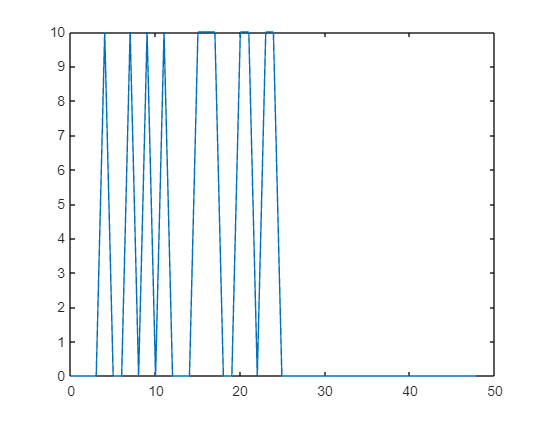

clc, close all, clear all

T = 24;              %segundos
Ts = 0.1;            %segundos/muestra
t = 0:Ts:T-Ts;       %vector tiempo de muestreo

f((t>0)&t<=3)=0;
f((t>3)&(t<=4))=1;
f((t>4)&(t<=6))=0;
f((t>6)&(t<=7))=1;
f((t>7)&(t<=8))=0;
f((t>8)&(t<=9))=1;
f((t>9)&(t<=10))=0;
f((t>10)&(t<=11))=1;
f((t>11)&(t<=14))=0;
f((t>14)&(t<=17))=1;
f((t>17)&(t<=19))=0;
f((t>19)&(t<=21))=1;
f((t>21)&(t<=22))=0;
f((t>22)&(t<=24))=1;

t2 = 0:0.1:50;

u = @(t) (t>=0);
x = @(t,d) u(t)-u(t-d);


%Señal impulso unitario
h = x(t,1);
y=conv(f,h,"full");
time = t(1)+t(1):0.1:t(length(t))+t(length(t));
plot(time,y);